# OURE 2024-2025

# FIR FILTER DESIGN (Window Method)

## IIR approach may be more suitable for realtime audio applications with variable Fc.

*More efficient computationally.*

## Table of Common Windowing Functions

*We will window the ideal LPF impulse response (sinc) in time.*

*Will apply and compare the results from these window functions.*

*Fs = Discrete sampling frequency*

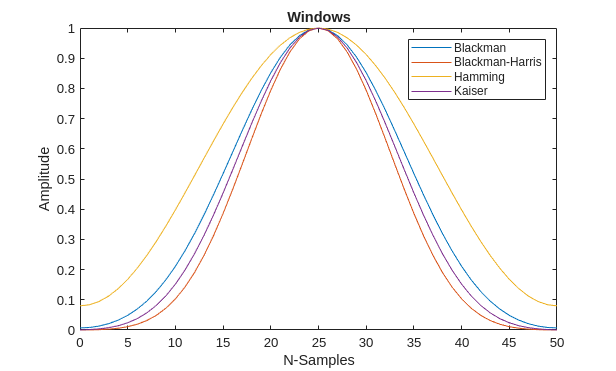

%M Filter order  = filter length - 1
M = 50;
Fs = 44.1e3; %44.1 kHz *typical audio Fs
fc = 1200; %1200 Hz
Fc = fc / (Fs); %Normalized frequency 
% set intervals = filter length
n = 0:1:M;
% beta value for kaiser
beta = 10;
%Hamming Window Function
wh = 0.54 - 0.46*cos(2*n*pi/M);
%Blackman Window Function
wb = 0.42659 - 0.49656*cos(2*pi*n/M) + 0.076849*cos(4*pi*n/M);
% Blackman-Harris window function
wbh = 0.35875 - 0.48829*cos(2*pi*n/M) + 0.14128*cos(4*pi*n/M) - 0.01168*cos(6*pi*n/M);
% Kaiser window function
wk = kaiser(M+1,beta)';

figure;
plot(n,wb,n,wbh,n,wh,n,wk)
xlim([0 M])
xlabel('N-Samples');
ylabel("Amplitude");
title('Windows');
legend('Blackman','Blackman-Harris','Hamming','Kaiser');

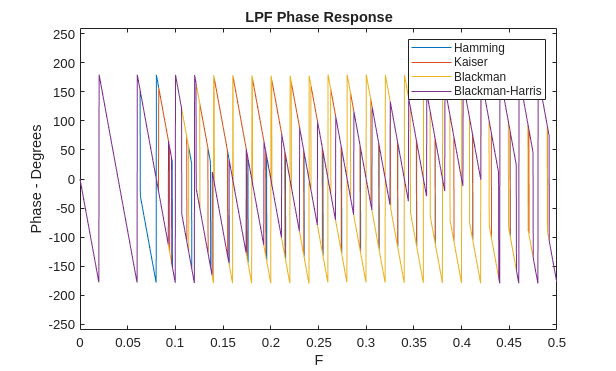

LPFimp = 2*Fc*sinc(2*Fc*(n-(M/2))); 
%IDEAL LPF in time domain



%%Multiply in time domain to create a windowed LPF 
LPFt_wh = LPFimp.*wh;
LPFt_wb = LPFimp.*wb;
LPFt_wbh = LPFimp.*wbh;
LPFt_wk = LPFimp.*wk;

%%perform a N point FFT 
N = 4096;
LPF_WH = fft(LPFt_wh,N);
LPF_WB = fft(LPFt_wb,N);
LPF_WBH = fft(LPFt_wbh,N);
LPF_WK = fft(LPFt_wk,N);
xlimits = 1:(N/2);


%%get gain in dB - Shorten to Fs = 0.5
LPFWHdb = 20*log10(abs(LPF_WH(xlimits)));
LPFBdb = 20*log10(abs(LPF_WB(xlimits)));
LPFBHdb = 20*log10(abs(LPF_WBH(xlimits)));(xlimits);
LPFKdb = 20*log10(abs(LPF_WK(xlimits)));

%Phase
Presponse1 = rad2deg(angle(LPF_WH(xlimits)));
Presponse2 = rad2deg(angle(LPF_WB(xlimits)));
Presponse3 = rad2deg(angle(LPF_WBH(xlimits)));
Presponse4 = rad2deg(angle(LPF_WK(xlimits)));


%Match vector size
n2 = (0:1:(N/2)-1);
n3 = n2/N;    %normalize freq axis
figure;
tiledlayout(2,2); % 2 rows, 2 columns


plot(n3,Presponse1,n3,Presponse2,n3,Presponse3,n3,Presponse4)
xlabel('F');
ylabel('Phase - Degrees');
ylim([-260,260]);
title('LPF Phase Response');
legend('Hamming','Kaiser','Blackman','Blackman-Harris');

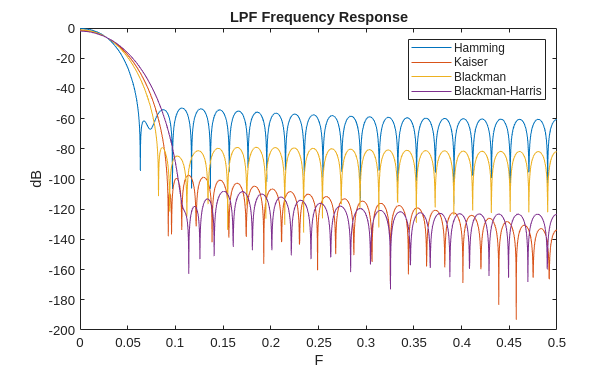



plot(n3,LPFWHdb,n3,LPFKdb,n3,LPFBdb,n3,LPFBHdb);
xlabel('F');
ylabel('dB');
title('LPF Frequency Response');
legend('Hamming','Kaiser','Blackman','Blackman-Harris');

*This next section will test the filters on a chirp signal that sweeps through the audible frequency range.*

*Plotting Power spectrum - Helpful when analyzing continuous spectra signals, displays the power component of the various frequencies present in the signal. *

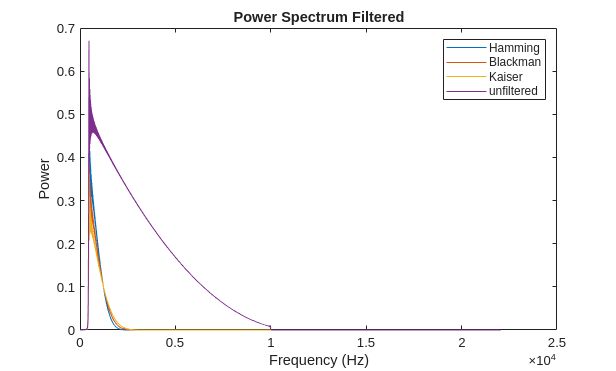

[x4,Fs] = audioread("chirp2.wav");
%Pad length of signal to the next power of 2 

length1 = pow2(nextpow2(length(x4)));

%FFT of audio signal
X = fft(x4,length1);

%%FFT of LPF - length1 points
LPF_WH1 = fft(LPFt_wh,length1);
LPF_WB1 = fft(LPFt_wb,length1);
LPF_WBH = fft(LPFt_wbh,length1);
LPF_WK = fft(LPFt_wbh,length1);

%Apply LPF to audio signal (Multiply in freq = convolution in time)
%apply a transpose to multiply with signal X
XnewH = X.*(LPF_WH1.');
XnewB = X.*(LPF_WB1.');
XnewBH = X.*(LPF_WBH.');
XnewK = X.*(LPF_WK.');

%Convert filtered signal back to time domain
Xtimeh = ifft(XnewH);
Xtimeb = ifft(XnewB);
Xtimebh = ifft(XnewBH);
XtimeK = ifft(XnewK);

%Play sound to check filter 
%sound(XtimeK,Fs);

Fn=(0:length1-1)*(Fs/length1); % maps your frequency variable axis
power = abs(X).^2/length1;  % calculates power of unfiltered signal
powerh = abs(XnewH).^2/length1; % calculates the power of the filtered signal 
powerb = abs(XnewB).^2/length1;
powerbh = abs(XnewBH).^2/length1;
powerk = abs(XnewK).^2/length1;


freqaxis = Fn(1:floor(length1/2));
figure
plot(freqaxis,powerh(1:floor(length1/2)),freqaxis,powerb(1:floor(length1/2)),freqaxis,powerk(1:floor(length1/2)),freqaxis,power(1:floor(length1/2))) % plots the power 
xlabel('Frequency (Hz)'); % labels the horizontal axis 
ylabel('Power'); % labels the vertical axis 
title('Power Spectrum Filtered'); % graph title
legend('Hamming','Blackman','Kaiser','unfiltered');

kLPF = dfilt.dffir(LPFt_wk);
hLPF = dfilt.dffir(LPFt_wh);
hLPF = dfilt.dffir(LPFt_wh);
bhLPF = dfilt.dffir(LPFt_wbh); %create filter object
bLPF = dfilt.dffir(LPFt_wb);

% fvtool(kLPF)
% fvtool(hLPF)
% fvtool(bhLPF)  %uncomment for filter tool for each
% fvtool(bLPF)

x4 =          0
    0.0501
    0.1000
    0.1496
    0.1985
    0.2468
    0.2938
    0.3400
    0.3846
    0.4280


ffs = 44100